# Clase 02_b >> Trabajando con señales

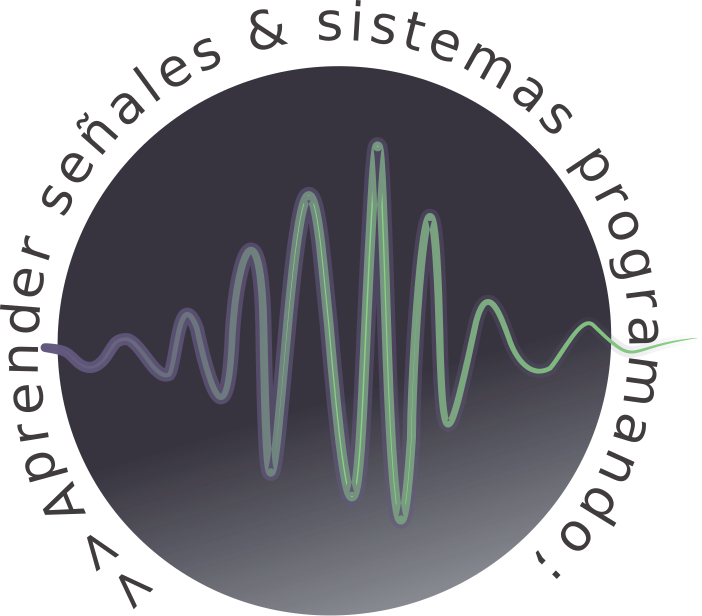

# Temario:

- Funciones (I).

- Debugging.

- Transformaciones de la variable independiente.

- Operaciones entre señales discretas.

- Figure, plot, stem, stairs y subplot.

- Title, xlabel, ylabel, legend y text.

- Dibujo de curvas en el pano.

- Visualización de matrices.

- Comentarios sobre los gráficos.

- Señales reales.

# Funciones (I)

Hasta ahora todas nuestras líneas fueron ejecutadas en **command windows **o en el **edit **como scripts para utilizarse secuencialmente, pero muy difícilmente podamos reutilizar este código en futuros proyectos con el fin de reducir tiempo de trabajo. 

Para lograr esto es necesario modificar la estructura de nuestro código, más precisamente de nuestro script y definir nuestras propias funciones, como las funciones predefinidas, por ejemplo:

help num2str

Podemos ingresar a la **estructura interna de esta función** si nos posicionamos en dicha función y presionamos <Ctrl+D>

**Las funciones** son archivos que pueden aceptar argumentos de entrada y  devolver argumentos de salida. Los nombres del archivo y de la función  deben ser iguales. Las funciones operan en variables dentro de su propia área de trabajo, en un espacio separado del área de trabajo a la que se accede desde la línea de comandos de MATLAB.

**Comencemos por aprender a guardar nuestras variables**

Abordar este tema es sumamente sencillo, uno de los caminos es realizarlo **directamente desde el workspace**, posicionándose en la variable de interés, hacer clic derecho y buscar la opción: "Save As...". Pero la idea de almacenar variables es poder utilizarlas en un futuro, para el caso de usarla en el entorno de MATLAB las indicadas son en formato .m, de otra forma si la intención es realizar un almacenamiento que pueda ser más genérico y leerlo con otros entornos conviene trabajar en .dat.

clc
clear all

a = magic(4);
b = ones(2, 4) * -5.7;
c = [8 6 4 2];
save -ascii mydata.dat a b c
clear a b c

load mydata.dat -ascii

## Definición de función

Una **función es una unidad de programa**, una tarea independiente que puede o no depender de variables externas. Las unidades de programa típicas son las funciones, las subrutinas, las clases... MATLAB basa toda su potencia y su sencillez en el constante uso de funciones [I Nogueras GB, 2007].

**Importante: **MATLAB no puede definir funciones directamente en el intérprete (Command Window). Cualquier función debe ser un archivo independiente por simple que esta sea. Ademas se debe respetar las misma reglas de nombramiento, como es en el caso de las variables.

Las funciones se crean del mismo modo que un script seleccionado en el menú **New/Function** y se guardan en un fichero que tiene el mismo nombre que la función y extensión .**m.**

La primera línea en el editor es la definición de la función que comienza con la palabra clave* function.*


$$\text{function variableSalida = nombreFuncion (variableEntrada)} \\
\qquad \text{sentencias} \\
\text{end}$$


- *nombreFuncion*, es el nombre significativo que se le  asigna a la función y coincide con el nombre del fichero de extensión .**m** en el que se guarda el código de dicha función. Las reglas para nombrar un función son las mismas que para las variables, los nombres no deben de incluir espacios, ni se pueden utilizar plabras reservadas por MATLAB. 

- *variablesEntrada*, es el conjunto de parámetros que se le pasa a la función. Los nombres de las variables van entre paréntesis y separadas por coma.

- *variabalesSalida*, es el valor o conjunto de valores de las variables devueltos por la función. Las variables de salida van después de la palabra reservada* function* entre corchetes cuadrados y separados por comas si hay varios.

- *sentencias*, líneas de código que tomando los valores de los parámetros de entrada calculan mediante expresiones los valores que devuelve la función.

- *end*, marca el final de la función es opcional (salvo en las funciones anidadas) pero es conveniente acostumbrarse a ponerlo al finalizar la función.   

**Opcionalmente**, en la segunda línea se pone un comentario (**docstring)**, en el que se explica la tarea que realiza la función. 

A continuación, una explicación detallada sobre las variables de entrada y de salida.

- Cuando una función **no** **devuelve ningún valor**, se define:

    
$$\text{function nombreFuncion (variableEntrada)} \\
\qquad \text{sentencias} \\
\text{end}$$


- Cuando una funcion** no precisa de variables de entrada** se define:

     
$$\text{function variableSalida = nombreFuncion \\
\qquad \text{sentencias} \\
\text{end}$$


- Cuando una función **devuelve un solo resultado** se define:

     
$$\text{function variableSalida = nombreFuncion (a,b,c) \\
\qquad \text{sentencias} \\
\text{end}$$


Una función se llama del mismo modo que las funciones predefinidas. Las funciones se pueden llamar desde la ventana de comandos, desde un fichero script o desde otra función. Ademas, todas las variables en una función son locales a dicha función, incluyendo las de entrada y las de salida. 

Para ejemplificar el uso de funciones vamos a retomar el último ejercicio y hacerlo con funciones, con el objetivo de hacerlo más generico y reutilizable.

***Observar**** la ventana Current Folder, para encontrar la diferencia entre Script y Function (Ordenar por tipo).*

## Tipos de funciones

- **Funciones anonimas**: es una forma simple de la función de MATLAB que se define dentro de una sola instrucción de MATLAB.

- **Funciones principales y subfunciones**: cualquier función que no sea anónima debe definirse dentro de un archivo. Cada archivo de función contiene una *función principal* que aparece primero, y cualquier número de *subfunciones* que pueden seguir a la principal.

- **Funciones privadas**: una *función privada* es un tipo de función principal. La característica que la distingue es que es visible solo para un grupo limitado de otras funciones. Este tipo de función puede ser útil si se desea limitar el acceso a una función, o cuando se escoge no exponer la implementación de una función. 

- **Funciones anidadas**: es posible definir funciones dentro del cuerpo de otra función. Se dice que estas se encuentran *anidadas* dentro de la función exterior. Una función anidada contiene algunos o todos los componentes de cualquier otra función.

## Ejercicios de la guía n°1  (script_02_02_b)

Resolver el ejercicio n°2 con un script en MATLAB, usando funciones.

Observación, la llamada a la función se puede hacer desde la ventana de comandos:

% open ('script_02_02_b.m')
script_02_02_b ()

## Ejercicios de la guía n°1  (script_02_03)

Realice el script necesario para resolver el ejercicio n°7 de la guia 1. Ademas, calcular la energia de una señal periodica y coroborrar que es **infinita**.

- Para las señales sinusoidales en **tiempo continuo**, una oscilación armónica se define como: 


$$X(t) = A\mathrm{cos}(\Omega t+\theta), -\infty<t>+\infty\quad,$$


donde $A$ es la amplitud, $\Omega(mayuscula)$es la frecuencia angular $\Omega = 2\pi F[rad/s]. \quad F[Hz] $ y fase $\theta [rad]$. Entonces una señal continua: 

figure

% Definición del eje temporal [s]
t_final = 24;
t = 0:1/1000:t_final; % imaginar que es lo más continúo posible
% Definición de la frecuencia [Hz][1/s]
f = 1/10;
% Definición de la función continua (Analógica)
xt = cos(2*pi*f*t);
% Ploteo de los resultados
plot(t,xt); title ('Señal continua' ); ylabel ('x(t)'); xlabel ('Tiempo [s]'); grid on;


$$\text{si sabemos que } \Omega = 2\pi f \longrightarrow {\Omega} = 2\pi / T \text{ Donde T [s] es el período}$$



$$X\quad \text{es períodica de período } T \Leftrightarrow X(t \pm T) = X(t), \text{ cuando } T = 2k\pi / {\Omega} \text{ con }k \in\mathbf{N}, \text{ para el } k \text{ más pequeño } T \text{ es } T_0 \text{ , período fundamental con } T_0 \in\mathbf{R}$$



$$\mathrm{cos}\left(2\pi t / 12\right) \text{ como } \Omega= \left (2\pi/12\right) \rightarrow T=\left(2k\pi12/2\pi\right)= 12k \text{ con } k=1  \rightarrow T_0=12$$


% open ('script_02_03.m')
help script_02_03
script_02_03 (2*pi/12,'t')
script_02_03 (2*pi,'t')

# Debugging

Continuando con el ultimo ejemplo, vamos a practicar como realizar un debugging o depuración de código:

- Para las señales sinusoidales en **tiempo discreto**, una oscilación armónica se define como: 


$$X[n] = A\mathrm{cos}[\omega n+\theta], -\infty<n>+\infty$$


Donde $A$ es la amplitud, $\omega(minuscula)$es la frecuencia angular $\omega = 2\pi f[rad/muestras], \quad f[Hz] $ y fase $\theta [rad]$. Entonces una señal discreta:

% Definición de los periodos de muestreo [s]
t_final = 24;
F = 2;
T1 = 1/F;
% Definicion de la cantindad de muestras en funcion de T
n = 0:1/F:t_final;
% Definición de la frecuencia [Hz]
f = 1/12;
% Definicion de las funciones discretas (Digital)
x1 = 2*cos(2*pi*f*n);
% Ploteo de los resultados
stem(n,x1);title (['Señal discreta muestreada a ',num2str(T1), 's']); ylabel ('x1[nT1]'); xlabel ('Tiempo [s]'); grid on; 


$$\text{si sabemos que } \omega = 2\pi f \longrightarrow \omega = 2\pi / N \text{ Donde N [1/s] es el período}$$



$$X\quad \text{es una señal periodica de periodo } N \Leftrightarrow X[n\pm N] = X[n] \text{ donde } N = \frac{2k\pi}{\omega} \text{ con }k\in\mathbf{N}, \text{para el } k \text{ más pequeño } N \text{ es } N_0  \text{ periodo fundamental con } N_0 \in\mathbf{Z}$$



$$\mathrm{cos}\left(2\pi n/ 12\right) \text{ como } \omega= \left (2\pi/12\right) \rightarrow N=\left(2k\pi12/2\pi\right)= 12k \text{ con } k=1  \rightarrow N=12$$


script_02_03(2*pi/12,'n')

Ayuda


$$mcm(\frac{a}{b},\frac{c}{d})=\frac{mcm(a,c)}{mcd(b,d)}$$



$$mcd(\frac{a}{b},\frac{c}{d})=\frac{mcd(a,c)}{mcm(b,d)}$$


help lcm
help gcd

# Transformaciones de la variable independiente 

Se sabe que dada una **secuencia discreta**:


$$x[n] \Rightarrow x[n \alpha + \beta].$$



$$\text{Si } \vert \alpha \vert < 1 \text{ se expande linealmente.}$$
 


$$\text{Si } \vert \alpha \vert > 1 \text{ se comprime linealmente.}$$



$$\text{Si } \alpha < 0 \text{ se invierte en el tiempo.}$$



$$\text{Si } \beta  < n \text{ con }n <0 \text{ son } n \text{ lugares a la derecha.}$$



$$\text{Si } \beta  > n \text{ con }n >0 \text{ son } n \text{ lugares a la izquierda.}$$



$$\text{Si  } x[n] \text{ es reflejado, entonces los movimientos son invertidos.}$$


Entonces que sucede con una señal expresada en 2 vectores:

x = [0 0 1 0 2 2 2 1 0 0]; % secuencia
n = -4:1:5; % indices

clf
stairs(n,x,'b'); title ('\it Transformacion de la variable independiente'); ylabel ('Amplitud'); xlabel ('n'); grid on; ylim([-1 3]);
hold on
stairs(n-(5),x,'r')  % mov. derecha
% stairs(n-(-5),x,'r')  % mov. izquierda
% stairs(-n,x,'r')  % inv. temporal
% stairs(n/abs(2),x,'r')  % comp
% stairs(n/abs(0.5),x,'r');  % exp
legend('Señal original','Señal transformada')
hold off

Otro ejemplo con una **secuencia continua** y combinando transformaciones:


$$x(t)=\begin{cases} 
0, \text{ para } -1<t<0 \\  
1, \text{  para } 0<t<2 \\
2-(t/2), \text{ para } 2<t<4 \\ 
0, \text{ para } 4<t<5 \\  
\end{cases}$$



$$y(t)=x(-2t+1)$$


t = -1:0.01:5;  % inicializo la variable independiente't'. Tamaño de t = 5-(-1)/0.01

% definición de la funcion por tramos
x1 = zeros(1,100);  % x(t) = 0 si -1 < t <0
x2 = ones(1,200);  % x(t) = 1 si  0 < t <2
x3 = 2-((1/2)*t(300:500));  % x(t) = 2-(t/2) si 2 < t < 4
x4 = zeros(1,100);  % x(t) = 0 si 4 < t < 5

Xt = [x1 x2 x3 x4];

tX = (t-1)/-2;  % tener cuidado con el orden de las operaciones

figure

plot(t,Xt); 
hold on
plot(tX,Xt); title ('\it Trasnformacion de la variable independiente'); ylabel ('Amplitud'); xlabel ('t'); grid on;
legend('Señal original','Señal transformada')
hold off

## Ejercicios de la guía n°1  (script_02_04)

Resolver el ejercicio n°3 con un script en MATLAB.

% open ('script_02_04.m')
script_02_04

# Operaciones entre señales discretas

## Suma de secuencias

Esto es una suma muestra a muestra dado por:


$$\left\lbrace x_1 \left\lbrack n\right\rbrack \right\rbrace +\left\lbrace x_2 \left\lbrack n\right\rbrack \right\rbrace =\left\lbrace x_1 \left\lbrack n\right\rbrack +x_2 \left\lbrack n\right\rbrack \right\rbrace$$


El problema de sumar secuencias radica en que $x_1 \left\lbrack n\right\rbrack$y $x_2 \left\lbrack n\right\rbrack$, deben tener la misma dimensiónes, para lo cual se agregan ceros en la secuencia faltante. En el caso de los vectores de indices, pueden ser distintos:

x1 = [0 0 1 2 3 0 0 2 2 0]; % secuencia n°1
n1 = [-2:1:7]; % indices n°1
x2 = [0 -2 -2 2 2 0 -2 0]; % secuencia n°2
n2 = [-3:1:4]; % indices n°2

% Graficar
stairs(n1,x1)
hold on
stairs(n2,x2)
n = min(min(n1),min(n2)):max(max(n1),max(n2)); % duracion y(n)

% Hacerlo paso a paso, verificando el workspace

% inicialización
y1 = zeros(1,length(n)); y2 = y1;
% x1 con duracion de y
y1(find((n>=min(n1))&(n<=max(n1))==1)) = x1;
% x2 con duracion de y
y2(find((n>=min(n2))&(n<=max(n2))==1)) = x2;
% suma
y = y1+y2
grid on
stairs(n,y)
legend('Secuencia_1','Secuencia_2','Secuencia_3')

## Multiplicación de secuencias

Esto es un producto muestra a muestra (o producto punto) dado por:


$$\left\lbrace x_1 \left\lbrack n\right\rbrack \right\rbrace \ldotp \left\lbrace x_2 \left\lbrack n\right\rbrack \right\rbrace =\left\lbrace x_1 \left\lbrack n\right\rbrack x_2 \left\lbrack n\right\rbrack \right\rbrace$$


El problema de multiplicar secuencia radica en que $x_1 \left\lbrack n\right\rbrack$y $x_2 \left\lbrack n\right\rbrack$, deben tener la misma dimensiónes, para lo cual se agregan ceros en la secuencia faltante. En el caso de los vectores de indices, pueden ser distintos:

x1 = [0 0 1 2 3 0 0 2 2 0]; % secuencia n°1
n1 = [-2:1:7]; % indices n°1
x2 = [0 -2 -2 2 2 0 -2 0]; % secuencia n°2
n2 = [-3:1:4]; % indices n°2

n = min(min(n1),min(n2)):max(max(n1),max(n2)); % duracion y(n)
y1 = zeros(1,length(n)); y2 = y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1; % x1 con duracion de y
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2; % x2 con duracion de y
y = y1 .* y2

## Ejercicios de la guía n°1  (script_02_05)

Resolver el ejercicio n°4 con un script en MATLAB. Empleando las señales discretas y representadas en la figura, obtener las siguientes señales (resolver mediante un gráfico y mediante una secuencia de números):

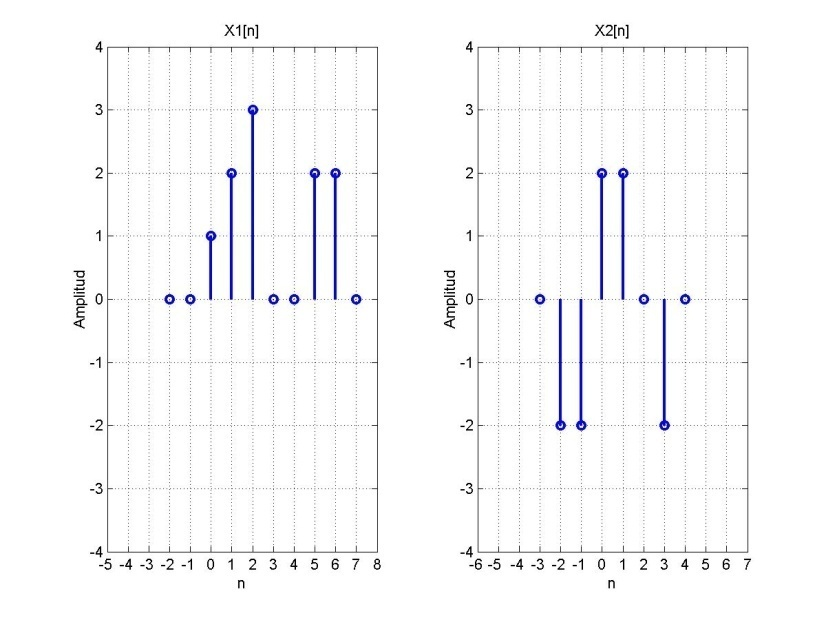


$$y_a[n] = x_1[n] + x_2[n]$$


% open ('script_02_05.m')
% Ejemplo del primer ejercicio
script_02_05 ()

## Ejercicios de la guía n°1  (script_02_06)

Resolver el ejercicio n°6 de la guia 1 con un script en MATLAB.

Sea la señal discreta $x[n]$ del siguiente gráfico:

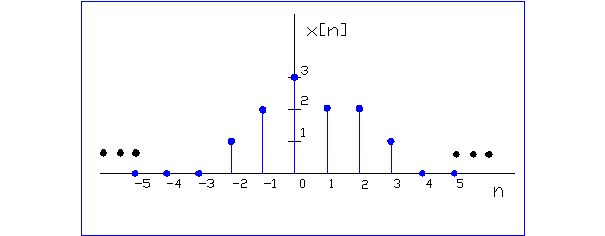

Para la señal $x[n]$ graficar mediante MATLAB las siguientes señales:


$$\frac{1}{2} x[n]+\frac{1}{2}(-1)^nx[n]$$


% Ejemplo del primer ejercicio
script_02_06 ()

# Figure, plot, stem, stairs y subplot

La representación gráfica de funciones y de series de puntos es uno de los fuertes de los lenguajes de scripting científico, en general. Todos ellos tienen rutinas para dibujar, de modo sencillo y rápido. MATLAB está orientado al dibujo de gráficas elementales, pero con un poco de esfuerzo es posible conseguir una gran calidad.

plot (secuencia continua de datos), stem (secuencia discreta de datos), stairs (escalonado)

## Figure

Cuando llamamos alguna función de representación gráfica MATLAB debe antes crear una ventana en el entorno gráfico, para ello usa la función **figure**. No es necesario que usemos esta función siempre; cuando no tengamos ninguna ventana activa MATLAB la llamará por defecto. Será necesario llamarla cuando queramos utilizar varias ventanas a la vez. Supongamos que acabamos de dibujar una secuencia "lo mas contínua posible" en una ventana nueva con (**probar los siguientes comandos, en "Command Window")**, para lo cual vamos hacer uso de la funcion **plot**:

plot(1:0.001:100)

MATLAB abrirá una ventana de nombre **figure 1** donde va a dibujar todo a partir de ahora. Si llamamos a otra rutina gráfica, sea cual sea, la va a dibujar en la ventana activa, **figure 1**. Si queremos dibujar en otra ventana tendremos que llamar la función **figure **usando como argumento el número de una ventana que no se encuentre activa, por ejemplo:

figure(2)

A partir de ahora la ventana 1 va a estar inactiva y todo lo que dibujemos va a expresarse en la ventana 2. **figure** también sirve para volver a dibujar en una ventana existente pero inactiva, sólo tenemos que darle como argumento el número de la ventana; en nuestro caso:

figure(1)

Cuando dibujamos en una ventana activa en la que ya había previamente una gráfica MATLAB la borra automáticamente. Lo que hace es llamar implícitamente la función **clf**. 

Ahora supongamos que se quiera superponer dos **secuencias discretas de datos**, en primer lugar usaremos la funcion **stairs** para su representacion (**nuevamente, probar los siguientes comandos, en "Command Window")**:

close all  % para cerrar todas las ventanas

x = [2,1,-1,0,1,4,3,7];
y = [-1,0,1,4,3,7];
figure(1)
stem(x)
figure(2)
stem(y)

Para que la nueva gráfica se superponga a la anterior usaremos la función **hold.**

close all  % para cerrar todas las ventanas

x = [2,1,-1,0,1,4,3,7];
y = [-1,0,1,4,3,7];

figure
stem(x)
hold on
stem(y)
hold off  % para cerrar

Ahora si, lo que buscamos es hacer una refresentacion escalonada de los datos, usamos las función **stairs**:

X = linspace(0,4*pi,40);
Y = sin(X);

figure
stairs(Y)

Podemos tener la necesidad de dibujar varias gráficas en una misma ventana, para ello existe la función **subplot. **Funciona exactamente igual que **figure **pero opera dentro de la misma ventana. Se llama con tres argumentos, el primero son el número de subgráficas por fila, el segundo el número de subgráficas por columna y el tercero es la subgráfica que activamos en cada momento. Por ejemplo el script:

x = linspace(-pi,pi,100)
subplot(2,2,1)
plot(x,sin(x))
subplot(2,2,2)
plot(x,cos(x))
subplot(2,2,3)
plot(x,sinh(x))
subplot(2,2,4)
plot(x,cosh(x))

**Podemos combinar las funciones plot, stem y stairs, en el uso de subplot.**

**Cada apartado de subplot es como una ventana a parte**, incluso en lo referente a títulos y nombres de ejes como veremos a continuación. Para activar y desactivar la cuadrícula se usa la función **grid on **y **grid off, **para activarla y desactivarla, respectivamente. Para ajustar los ejes a los valores deseados tenemos la función **axes **que hay que pasarle un vector de datos.

# Title, xlabel, ylabel, legend y text

Otro de los requerimientos de una gráfica es poder añadir un título y nombres a los ejes y a las curvas. **title**, **xlabel** y **ylabel **funcionan de manera idéntica; si les pasamos una cadena de texto la tomarán por el nombre de la gráfica, del eje x y del eje y respectivamente.

clf
x = linspace(0, 500, 10000)
plot(x,exp(-x/100).*sin(x))
title('Una funcion cualquiera')
xlabel('Tiempo')
ylabel('Amplitud')

En el caso que tengamos varias curvas en la misma gráfica podemos dar un nombre a cada una de ellas mediante la función **legend.** También podemos introducir en los gráficos caracteres especiales o letras griegas. Para hacerlo hay que tener nociones básicas de LaTex, MATLAB por defecto interpreta todos los caracteres empezados con una barra invertida $ \$ como palabras clave en LaTex.

x = linspace(0, 500, 10000);
plot(x,exp(-x/100).*sin(x))
title('${\it A e} ^{- \alpha \it t}sin \beta{ \it t} \alpha<< \beta$','Interpreter','latex')
xlabel('Tiempo ($\mu s$)','Interpreter','latex')
ylabel('Amplitud (mV)','Interpreter','latex')

# Dibujo de curvas en el pano

Si queremos pasarle más argumentos plot los va a interpretar de la forma:

`plot(X,Y,FMT,X,Y,FMT,X...)`

Los elementos X e Y son interpretados del modo siguiente: si ambos argumentos son vectores se representa la serie de puntos definida por los dos; esto implica que deben ser de la misma longitud. Si el primer argumento es un vector y el segundo es una matriz se representan las curvas correspondientes al vector junto con cada una de las o columnas de la matriz. Se prueban primero las columnas, si es imposible la representación luego se prueban las filas; si ambos fallan se obtiene un mensaje de error. Si el primer argumento es una matriz y el segundo es un vector se actúa de la misma manera. Si ambos argumentos som matrices se toman como datos para curva las columnas; requerirá que tengan una forma idéntica. FMT es el argumento que define el tipo de línea. Es una cadena de texto y en su ausencia se tomará como formato básico la línea sólida. Para saber los tipos y colores de líneas disponibles mediante el formato consultaremos la ayuda.

x=linspace(-pi,pi,100);
plot(x,sin(x),'m:',x,cos(x),'k ^',x,tan(x),'bx')
axis([-pi,pi,-2,2])
grid on
legend('linea de puntos magentas','triangulos negros','cruces azules')

# Vizualización de matrices 

Todas las matrices pueden ser visualizadas:

mat = reshape(1:10000,100,100);
imagesc(mat); 
%colorbar; 
%colormap(gray)
colormap(cool)
caxis ([6000 7000]);

Dado,


$$f(x,y) = sin(x)cos(y) \text{con } x\in [-\pi,\pi]; y\in  [-\pi,\pi].$$


x = -pi:0.1:pi;
y = -pi:0.1:pi;
[X,Y] = meshgrid(x,y);
Z = sin(X).*cos(Y);
surf(X,Y,Z)
shading faceted
% shading flat
% shading interp
contour(X,Y,Z,'LineWidth',2);colorbar;

# Comentarios sobre los gráficos

Las posibilidades de graficar con MATLAB son muy diversas, no solo en tipos y estilos, sino ademas en la forma de definir el entorno de trabajo. Por este motivo es recomendable usar el **help **para ver todas las opciones disponibles. A continuacion una lista de las funciones más útiles.

- **plot()**, crea un gráfico a partir de vectores y/o columnas de matrices, con escalas lineales sobre ambos ejes.

- **semilogx()**, ídem con escala lineal en el eje de ordenadas y logarítmica en el eje de abscisas.

- **semilogy()**, ídem con escala lineal en el eje de abscisas y logarítmica en el eje de ordenadas.

- **line()**, permite dibujar una o más líneas que unen los puntos cuyas coordenadas se pasan como argumentos.

- **bar()**, crea diagramas de barras.

- **hist(),** dibuja histogramas de un vector.

Más info en:

helpwin plot

Mostrar el uso de `editPlot.`

# Señales reales

## ¿Una señal de audio audio es una señal discreta?

Si, siempre y cuando la señal pase por un proceso de digitalización previo obtendremos una señal muestreada. Por lo tanto podremos hacer las transformaciones que vimos anteriormente. 

Por ejemplo, comencemos cargando un archivo con datos de audio:

clc
clear all

% load handel.mat
load gong.mat;

Si observamos el workspace, tenemos dos variables: la frecuencia de muestreo del archivo (Fs) y los datos del audio (y). Rapidamente podemos hacer dos observaciones, la primera que es un vector columna por lo tanto la señal es mono y segundo un calculo de la duración del mismo:

duracion = seconds(numel(y)/Fs)     % En segundos dado que Fs [1/s]

Como se menciono anteriormete estos son datos y no un archivo de audio, para poder escuchar o obtener informacion del mismo debemos crear el archivo de audio:

audiowrite('gong.wav',y*0.8,Fs,'Comment','Este es mi nuevo archivo de audio','Artist','UNTREF')


Alternativa

audiowrite('gong.wav',y/max(y),Fs*2,'Comment','Este es mi nuevo archivo de audio','Artist','UNTREF')
clear y Fs

La función **audiowrite y audior****ead** escribe y lee en otros formatos por ejemplo: OGG, FLAC, and MPEG-4 AAC. 

Para obtener información del archivo:

info = audioinfo('gong.wav')

Para leer un archivo de audio:

[y, Fs] = audioread('gong.wav')

Reproducir audio:

sound(y,Fs)

Para graficar dicha señal es necesario crear un vector t con el mismo largo de , que representa el tiempo:

t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);

Graficar la señal de audio en función del tiempo:

plot(t,y)
xlabel('Tiempo')
ylabel('Señal de audio')
% soundview(y,Fs)

## Operaciones entre señales discretas REALES ( script_02_07)

Este ejercicio propone aplicar lo aprendido anteriormente, sobre señales de audio. Para tal fin la idea es sumar dos señales en un script que tiene como argumentos principales la señal de audio, el tiempo de desplazamiento y la amplitud de la señal a sumar :


$$y[n] = x[n] + \text{A}*x[n-\text{msec}]$$


Es importante aclara que esta forma no es la más optima para agregar un delay.

clc
clear all

script_02_07 ('vocal.wav',80,0.5)

La longitud de una secuencia finita puede incrementarse añadiendo muestras de valor cero *(zero padding)*.

# Referencias

- I Nogueras GB. **Introducción informal a Matlab y Octave**. 2007.

- Oppenheim, Alan V.; Willsky, Alan S.; Nawab, S. Hamid. ***Señales y sistemas***. Pearson Educación, 1998.